clc;clear all; close all;
%initialization
% Lx=40;%width of platform
% Ly=10;%length of platform
Lx=180;%width of platform
Ly=20;%length of platform

dx=2;% del x
dy=2;%del y
nx=(Lx/dx)+1;% no. of nodes in x direction
ny=(Ly/dy)+1;%no of nodes in y direction
m=nx*ny;
% nx=4;
% ny=4;
lambda=23;% thermal diffusivity of iron 
d=2;%2mm thickness

Conductive heat transfer can be expressed with "**Fourier's Law**"

*q = (k / s) A dT  = U A dT  *

*where*

*q = heat transfer (W, J/s, Btu/hr)*

*k =* [*Thermal Conductivity of material*](https://www.engineeringtoolbox.com/thermal-conductivity-d_429.html) *(W/m K or W/m* *o**C, Btu/(hr* *o**F ft**2**/ft))*

*s = material thickness (m, ft)*

*A = heat transfer area (m**2**, ft**2**)*

*U = k / s*

*   = * [*Coefficient of Heat Transfer*](https://www.engineeringtoolbox.com/overall-heat-transfer-coefficient-d_434.html) *(W/(m**2**K), **Btu/(ft**2* *h* *o**F)**dT = t**1* *- t**2*

*    = temperature gradient - difference - over the material (**o**C,* *o**F)*


Nodes=1:1:nx*ny;
%no of rows=ny, no. of columns=nx
grid_nodes= reshape(Nodes,[ny,nx])

grid_nodes =      1    12    23    34    45    56    67    78    89   100   111   122   133   144   155   166   177   188   199   210   221   232   243   254   265   276   287   298   309   320   331   342   353   364   375   386   397   408   419   430   441   452   463   474   485   496   507   518   529   540
     2    13    24    35    46    57    68    79    90   101   112   123   134   145   156   167   178   189   200   211   222   233   244   255   266   277   288   299   310   321   332   343   354   365   376   387   398   409   420   431   442   453   464   475   486   497   508   519   530   541
     3    14    25    36    47    58    69    80    91   102   113   124   135   146   157   168   179   190   201   212   223   234   245   256   267   278   289   300   311   322   333   344   355   366   377   388   399   410   421   432   443   454   465   476   487   498   509   520   531   542
     4    15    26    37    48    59    70    81    92   103   114   125   136   147

source=grid_nodes(1:4,1:4);%heat source nodes (top left corner)
% source=grid_nodes(1,1:26)
% source=grid_nodes(1:4,88:91);%heat source nodes (top right corner)
% source=grid_nodes(8:11,88:91);%heat source nodes (bottom right corner)
% source=grid_nodes(8:11,1:4);%heat source nodes (bottom left corner)
%source=grid_nodes(4:7,44:47);%heat source nodes (centre)
% source=grid_nodes(4:7,1:4);%heat source nodes (left edge)
%source=grid_nodes(6:9,30:33);%heat source nodes (random point inside plate)


%%%%%%%%% new source for smaller grid
% source=grid_nodes(1:2,18:21);%heat source nodes (top right corner)
% source=grid_nodes(3:4,1:4);%heat source nodes (left edge)
% source=grid_nodes(4:5,7:10);%heat source nodes (inside plate)



M=eye(m);%inertia matrix
%A matrix formulation
A=A_matrix(nx,ny,dx,dy,grid_nodes);


A=lambda*A;
L=inv(M)*A;
%B matrix formation
B=B_matrix(nx,ny,grid_nodes,d,source);
F=inv(M)*B;
% visualization of network structure
Ad=L;%adjancey matrix
for i=1:nx*ny
    Ad(i,i)=0;
end

% convert the matrix to sparse matrix
Ad=sparse(Ad);
eigen_values= Laplacian_check(L);

there are more than one zero eigen value , hence matrix is not laplacian
row sum is zero


col = "column  sum is zero"

column  sum is zero
A is symmetric
It is a Undirected Graph


s=sparse(L);
g=graph(Ad);
% figure(1)
% h=plot(g);
% title('visualization of network structure')

% dissimilarity matrix computation
[D,P,P0,Q]= dissimilarity_matrix(nx,ny,L,F,M);

p verified
P0 verified
D is symmetric


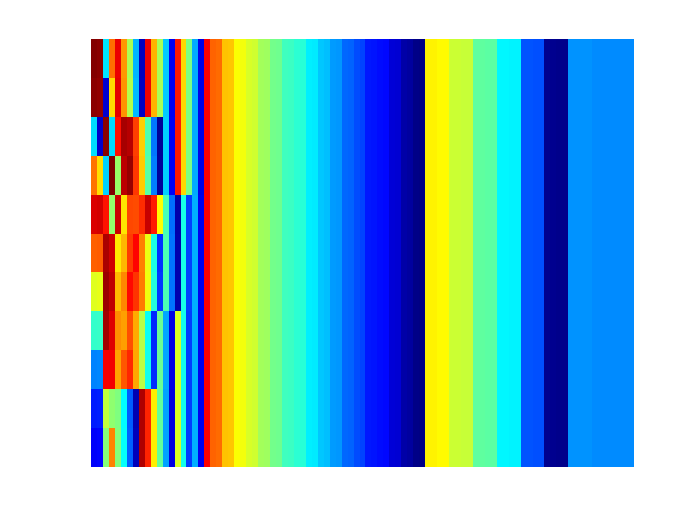


% clustering
% convert D to a vector form
d = squareform(D);
% call linkage function
Z = linkage(d,'complete');
% plot dendrogram
% figure(3)
% dendrogram(Z)
% title('dendogram')
nc=200;%number of clusters
T = cluster(Z,'MaxClust',nc);
net_cluster=reshape(T,[ny,nx]);

%grid network cluster visualisation
figure(1)
colormap jet
gg=imagesc(net_cluster);
axis off;
grid off
saveas(gcf,'cluster centre .png')

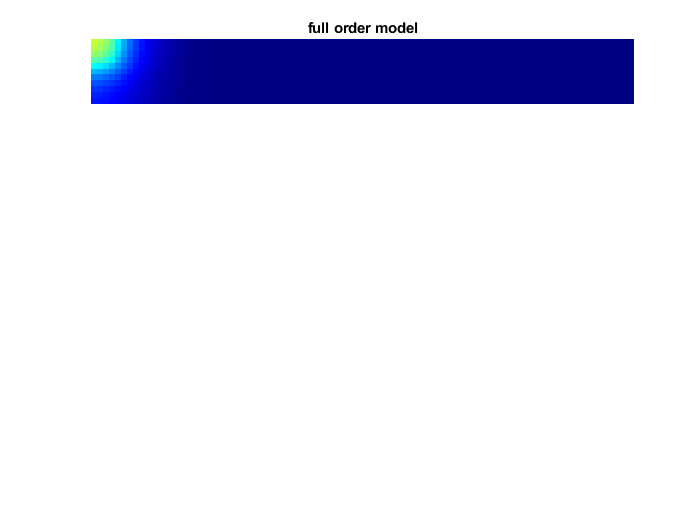

Index in position 1 exceeds array bounds (must not exceed 101).

Error in odesolver (line 45)
     temp=x(400,:);


%calculation of PI matrix 
PI=PI_matrix(T);
PI_inv=inv(PI'*M*PI)*PI'*M;%dont use pinv command, instead find manually
heater=75;
%solve ode
% prompt = 'type 1 for ode solver and 2  to skip simulation ';
% choice = input(prompt)
choice=1;
while (choice==1 || choice==2)
    if choice==1;
        % ode solver
        tspan = 0:1:100;
        Xo=0*ones(1,nx*ny)';
        u=heater*ones(1,nx*ny)';
        [t,x]=odesolver(Xo,A,B,u,tspan,ny,nx);
        break
        
    else choice==2;

        break
    end
end


% Reduced order network response
% ode solver
%Laplacian check for the reduced order model
Mr=PI'*M*PI;
Lr=PI'*L*PI;
eb= Laplacian_check(Lr);
% prompt = 'type 1 for ode solver and 2  to skip simulation ';
% choice = input(prompt);
choice=1;
while (choice==1 || choice==2)
    if choice==1
        tspan = 0:1:100;
        Xo=0*ones(1,nx*ny)';
        u=heater*ones(1,nx*ny)';
        Zo=PI_inv*Xo;
        u_r=heater*ones(1,nc)';
        
%         Zo=pinv(PI)*Xo;
%         u_r=pinv(PI)*u;
        [t,z]=odesolver_reduced(Zo,A,B,u_r,PI,tspan,ny,nx,M);
        break
        
    else choice==2

        break
    end
end



%
%Network visualization

% figure(6)
% colormap hsv
% nSizes =2*T;
% nColors = T;
% net=plot(g,'MarkerSize',nSizes,'NodeCData',nColors,'EdgeAlpha',0.5);
% title('visualization of network structure with max clusters =3')
% % colorbar
% 
% 
% 
% % comparison
% prompt = 'type 1 for ode solver and 2  to skip simulation ';
% choice = input(prompt)
choice=1;
while (choice==1 || choice==2)
    if choice==1;
        [t1,z,t2,x]=odesolver_comparison(Zo,Xo,A,B,u,u_r,PI,tspan,ny,nx,M);
        break
        
    else choice==2;

        break
    end
end

## error approximation

Let Po and Pr be the pseudo controllability Gramians ofthe full-order and reducedorder network systems, Σ and $\hat{\Sigma}$, respectively. Then, the approximation error between Σ and $\hat{\Sigma}$ is computed as


$$$$\|\mathbf{\Sigma}-\hat{\mathbf{\Sigma}}\|_{\mathcal{H}_{2}}^{2}=tr\left[H\left(\mathcal{P}_{o}+\Pi \mathcal{P}_{r} \Pi^{T}-2 \Pi \mathcal{P}_{x}\right) H^{T}\right]$$$$


where $\mathcal{P}_{x}:=\tilde{\mathcal{P}}_{x}-\Pi^{\dagger} \mathcal{J} \Pi \tilde{\mathcal{P}}_{x} \mathcal{J}^{T} \in \mathbb{R}^{r \times n}$

with $\tilde{\mathcal{P}}_{x}$ an arbitrary symmetric solution ofthe following Sylvester equation:


$$$\hat{\mathcal{L}}^{T} \tilde{\mathcal{P}}_{x}+\tilde{\mathcal{P}}_{x} \mathcal{L}^{T}-\Pi^{\dagger}(I-\mathcal{J}) F F^{T}\left(I-\mathcal{J}^{T}\right)=0$$$


%error approximation of the number of  clusters taken
% [error_approx,P,Pr,Px]= reduced_model_error(nx,ny,PI,L,F);

clf;
e=[];
c=[];
% errorapprox vs no.of cluster
for n=10:10:400
    nc=n;
    T = cluster(Z,'MaxClust',n);
    PI=PI_matrix(T);
    [error_approx,Pr,Px]= reduced_model_error(nx,ny,PI,L,F,P,M);
    e=[e error_approx];
    c=[c nc];
%     figure(8)
%     plot(c,error_approx)


%     s=scatter(c,error_approx);
%     s.LineWidth = 0.6;
%     s.MarkerEdgeColor = 'b';
%     s.MarkerFaceColor = [0 0.5 0.5];
%     xlabel('number of clusters')
%     ylabel('error')
%     hold on    

end
figure(8)
plot(c,e,'-o','LineWidth',2,...
    'MarkerSize',4,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])
%     s=scatter(c,error_approx);
%     s.LineWidth = 0.6;
%     s.MarkerEdgeColor = 'b';
%     s.MarkerFaceColor = [0 0.5 0.5];
 xlabel('number of clusters')
 ylabel('error')
 






%% find the optimal sensor node
%n is no.of clusters.
clc;
ror=reshape(state_error,[1,nx*ny]);
for i=1:1:n
    group=[];
    k=[];
    for j=1:1:length(T)
        if T(j)==i
            group=[group ror(j)];
        else
            continue
        end
    end
    minimum_error=min(group);
    k=find(ror==minimum_error(1));
    ror(k)=20 ;   
end
figure(9)
subplot(1,2,1)
ror=reshape(ror,[nx,ny]);
heatmap(ror);
subplot(1,2,2)
gg=heatmap(net_cluster,'Colormap',hot);

figure(10)
I = imread('cluster centre .png');
bw = rgb2gray( I );
ed=edge(bw,'Canny');
%ed=imcomplement(ed);
imshow(ed)